# Test EMG Data

Sam Coleman and Rishita Sarin

Used our 3 trained classifiers on our testing data to see accuracy

load ("data/trainedAlgorithms.mat");
load("data/testFeatures.mat");

## Test Algorithm 1

Average Amplitude Change (AAC) and Mean of Absolute Value (abs_mean). Only channels 1 and 2

features1 = [emg_aac(1:2, :); emg_abs_mean(1:2, :)]';
test_labels1 = predict(trainedAlg1, features1);
testAccuracy1 = sum(test_labels1==emg.epochlabelscat')./length(test_labels1);
fprintf('\n Algorithm 1 test accuracy = %.2f%%\n', testAccuracy1*100);


 Algorithm 1 test accuracy = 86.11%


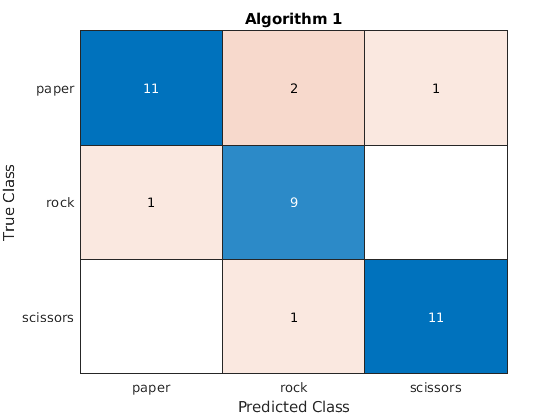

confusion_mat1 = confusionchart(test_labels1, emg.epochlabelscat);
title("Algorithm 1")

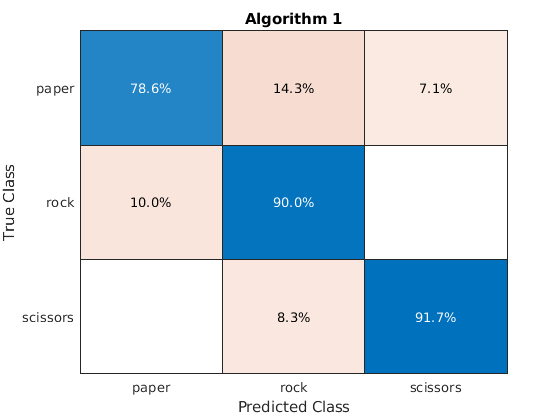

confusion_mat_norm1 = confusionchart(test_labels1, emg.epochlabelscat, 'Normalization','row-normalized');
title("Algorithm 1")

## Test Algorithm 2

Root mean square (RMS). Only channels 1 and 2

features2 = [emg_rms(1:2, :)]';
test_labels2 = predict(trainedAlg2, features2);
testAccuracy2 = sum(test_labels2==emg.epochlabelscat')./length(test_labels2);
fprintf('\n Algorithm 2test accuracy = %.2f%%\n', testAccuracy2*100);


 Algorithm 2test accuracy = 80.56%


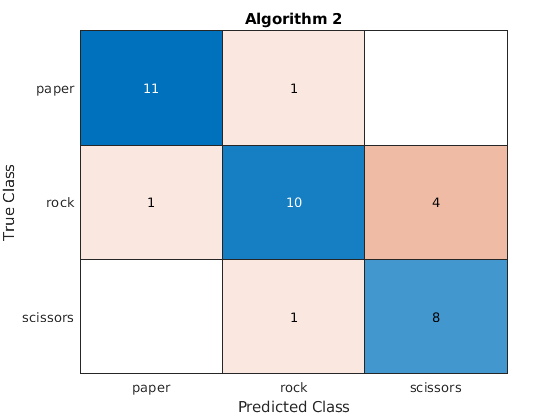

confusion_mat2 = confusionchart(test_labels2, emg.epochlabelscat);
title("Algorithm 2")

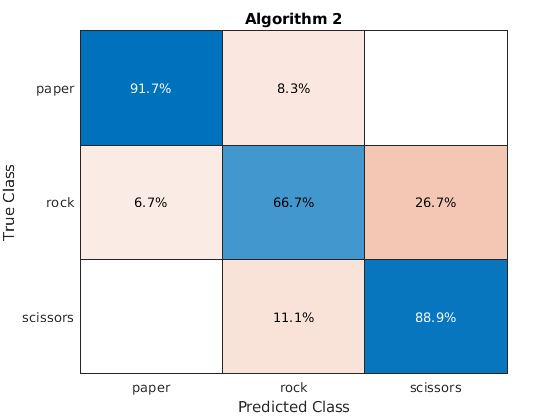

confusion_mat_norm2 = confusionchart(test_labels2, emg.epochlabelscat, 'Normalization','row-normalized');
title("Algorithm 2")

## Test Algorithm 3

Average Amplitude Change (AAC), Mean of Absolute Value (abs_mean), Kurtosis (kurt), and Mean. Only channels 1 and 2

features3 = [emg_aac(1:2, :); emg_abs_mean(1:2, :); emg_kurt(1:2, :); emg_mean(1:2, :)]';
test_labels3 = predict(trainedAlg3, features3);
testAccuracy3 = sum(test_labels3==emg.epochlabelscat')./length(test_labe[] ...
    ...
    ls3);
fprintf('\n Algorithm 3 test accuracy = %.2f%%\n', testAccuracy3*100);


 Algorithm 3 test accuracy = 83.33%


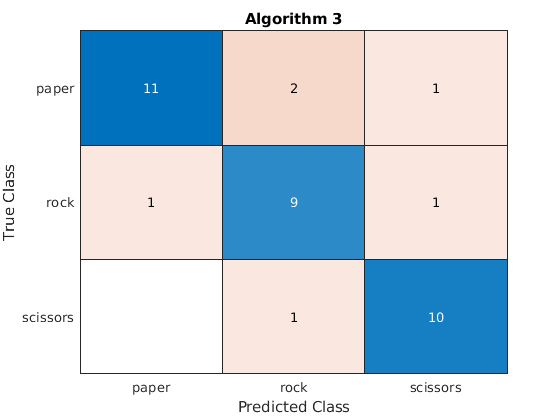

confusion_mat3 = confusionchart(test_labels3, emg.epochlabelscat);
title("Algorithm 3")

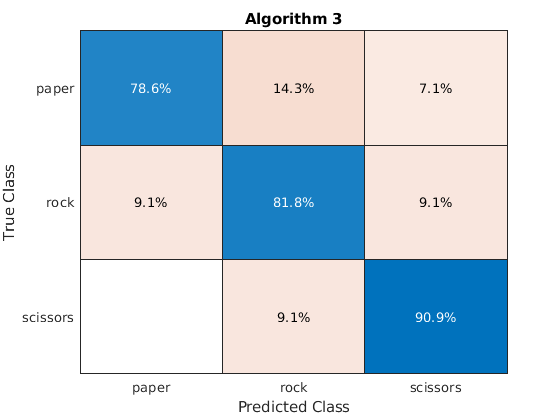

confusion_mat_norm3 = confusionchart(test_labels3, emg.epochlabelscat, 'Normalization','row-normalized');
title("Algorithm 3")